# Perform Pick and Place in Robot Scenario

Create a [`robotScenario`](docid:robotics_ref#mw_146ff228-e368-41e9-ac10-b70d38e44bd8) object.

scenario = robotScenario(UpdateRate=1,StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the Franka Emika Panda manipulator using [`loadrobot`](docid:robotics_ref#mw_5c29228c-fb8f-4ca4-9d7e-eecb323f1a74).

addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF/urdf")  % Louie Path folder
% addpath("C:\Users\dnehu\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF\urdf")  % Dan path folder
savepath % Save filepath for next time

% Create a rigidBodyTree object of the Franka Emika Panda manipulator using loadrobot.
robotRBT = importrobot("Robot_URDF.urdf");

Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

robot = robotPlatform("Manipulator",scenario, ...
                      RigidBodyTree=robotRBT);

Create a non-`rigidBodyTree`-based `robotPlatform` object of a box to manipulate. Specify the mesh type and size.

box = robotPlatform("Box",scenario,Collision="mesh", ...
                    InitialBasePosition=[0 0.2 0.2]);
updateMesh(box,"Cuboid",Collision="mesh",Size=[0.06 0.06 0.1])

Visualize the scenario.

ax = show3D(scenario,Collisions="off");
view(79,36)
light

Specify the initial and the pick-up joint configuration of the manipulator, to move the manipulator from its initial pose to close to the box.

initialConfig = homeConfiguration(robot.RigidBodyTree);
pickUpConfig = [-1.57079632679490, 0.163747126400824 1.96347342556597, -2.12722055196679, -0.015, 0.015];

Create an RRT path planner using the [`manipulatorRRT`](docid:robotics_ref#mw_ebddba4d-1dbe-4a60-b626-74349473c4bb) object, and specify the manipulator model.

planner = manipulatorRRT(robot.RigidBodyTree,scenario.CollisionMeshes);
planner.IgnoreSelfCollision = true;

Plan the path between the initial and the pick-up joint configurations. Then, to visualize the entire path, interpolate the path into small steps.

rng("default")
path = plan(planner,initialConfig,pickUpConfig);
path = interpolate(planner,path,25);

Set up the simulation.

setup(scenario)

Check the collision before manipulator picks up the box.

checkCollision(robot,"Box", ...
               IgnoreSelfCollision="on")

ans = logical
   1


Move the joints of the manipulator along the path and visualize the scenario.

helperRobotMove(path,robot,scenario,ax)

Check the collision after manipulator picks up the box.

checkCollision(robot,"Box", ...
               IgnoreSelfCollision="on")

ans = logical
   1


Use the [`attach`](docid:robotics_ref#mw_f599e87b-4d9e-47b8-8413-6e561832321c) function to attach the box to the gripper of the manipulator.

attach(robot,"Box","End_Effector_1", ...
       ChildToParentTransform=trvec2tform([0 0 0.1]))

Specify the drop-off joint configuration of the manipulator to move the manipulator from its pick-up pose to the box drop-off pose.

dropOffConfig = homeConfiguration(robot.RigidBodyTree);

Plan the path between the pick-up and drop-off joint configurations.

path = plan(planner,pickUpConfig,dropOffConfig);
path = interpolate(planner,path,25);

Move the joints of the manipulator along the path and visualize the scenario.

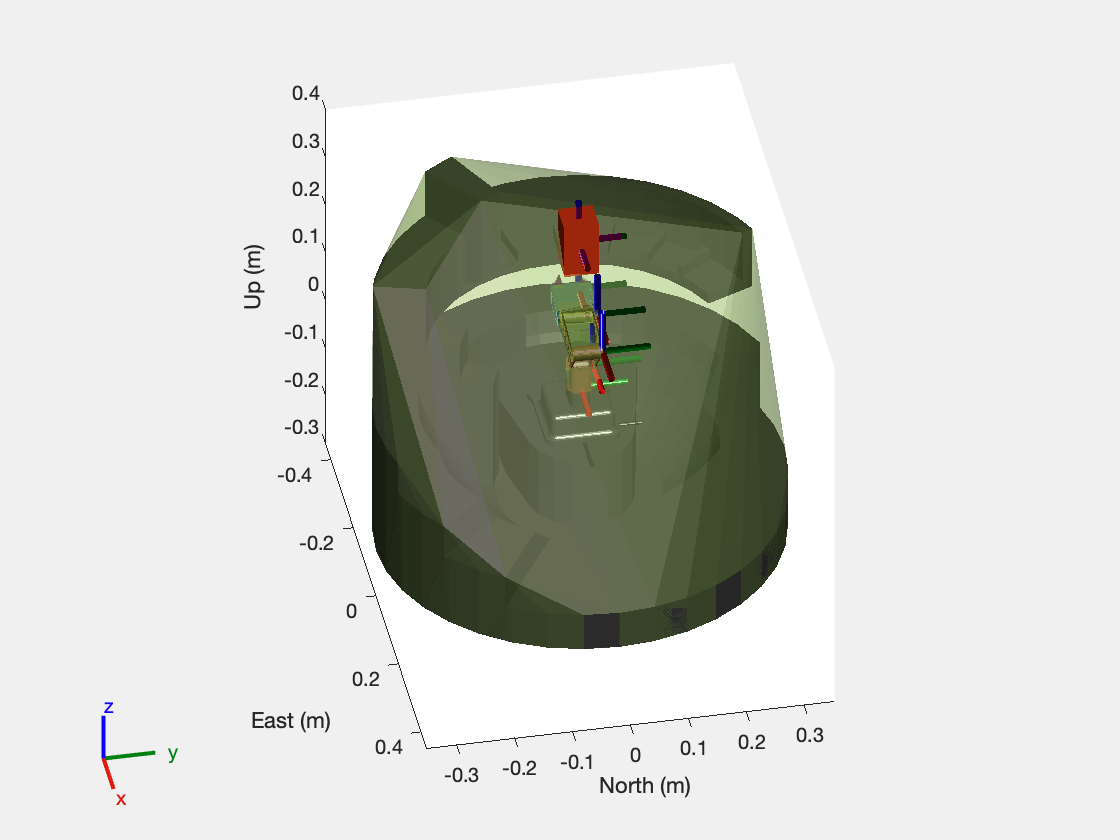

helperRobotMove(path,robot,scenario,ax)

Use the [`detach`](docid:robotics_ref#mw_2c3654b9-76f1-441e-8c6d-651b3771c899) function to detach the box from the manipulator gripper.

detach(robot)

Plan the path between the drop-off and initial joint configurations to move the manipulator from its box drop-off pose to its initial pose.

path = plan(planner,dropOffConfig,initialConfig);
path = interpolate(planner,path,25);

Move the joints of the manipulator along the path and visualize the scenario.

helperRobotMove(path,robot,scenario,ax)*1

Error using PickandPlaceRoughWorking>helperRobotMove
Too many output arguments.

Helper function to move the joints of the manipulator.

function helperRobotMove(path,robot,scenario,ax)
    for idx = 1:size(path,1)
        jointConfig = path(idx,:);
        move(robot,"joint",jointConfig)
        show3D(scenario,fastUpdate=true,Parent=ax,Collisions="on");
        drawnow
        advance(scenario);
    end
end

*Copyright 2022 The MathWorks, Inc.*